# Fitting models that require data from multiple set sizes

Several of the models in the MemToolbox **fit data across multiple set sizes** with a likelihood function that depends on the number of items on the display. For example,** the slots+averaging model** of Zhang and Luck (2008) postulates that there are a **fixed number of memory slots available to observers**, and thus is committed to the idea that the **guess rate and standard deviation should be predictable across set size**, based on the number of slots present and the amount of information contained in a slot. To use such models, you must provide a data struct that contains a set size field, n. This field says, for each trial, how many items were present

The standard plotting functions of the MemToolbox are useful in this case, but, by virtue of the fact that **they plot all of the data together (collapsing across set size),** they do not provide the best visualizations of this kind of data. Rather than asking if the model fits the average data across all of the set sizes, it is often more **informative to look at the fits and model residuals for each set size individually.**

For this reason, all of the plotting functions of the MemToolbox which depend on the data create figures that have an additional menu added to them, labeled MemToolbox. This menu allows you to limit the data being shown to a particular set size.

the SlotsPlusAveragingModel correctly predicts all of the data, and the data when limited to just set size 2, and the data when limited to just set size 5. If you fit the same data with the StandardMixtureModel, it would fit total data OK, but would fail to fit the set sizes properly (since it would use the same parameters for every set size).

clear all;
data = MemDataset(10)

data = struct with fields:
         n: [1×1000 double]
    errors: [1×1000 double]



Error histogram:   -180 _________.'._________ +180
          Model:   Slots+averaging model
     Parameters:   capacity, sd

Just a moment while MTB fits a model to your data...

   Running 3 chains...
   ... not yet converged (200); btw/within variance: 8.20
   ... not yet converged (400); btw/within variance: 30.54
   ... not yet converged (600); btw/within variance: 26.32
   ... not yet converged (800); btw/within variance: 15.83
   ... not yet converged (1000); btw/within variance: 6.16
   ... not yet converged (1200); btw/within variance: 1.89
   ... not yet converged (1400); btw/within variance: 1.28
   ... chains converged after 1600 samples!
   ... collecting 4500 samples from converged distribution

...finished. Now let's view the results:

parameter	MAP estimate	lower CI	upper CI
---------	------------	--------	--------
capacity	       2.975	   2.732	   3.246
      sd	      19.688	  18.396	  21.279



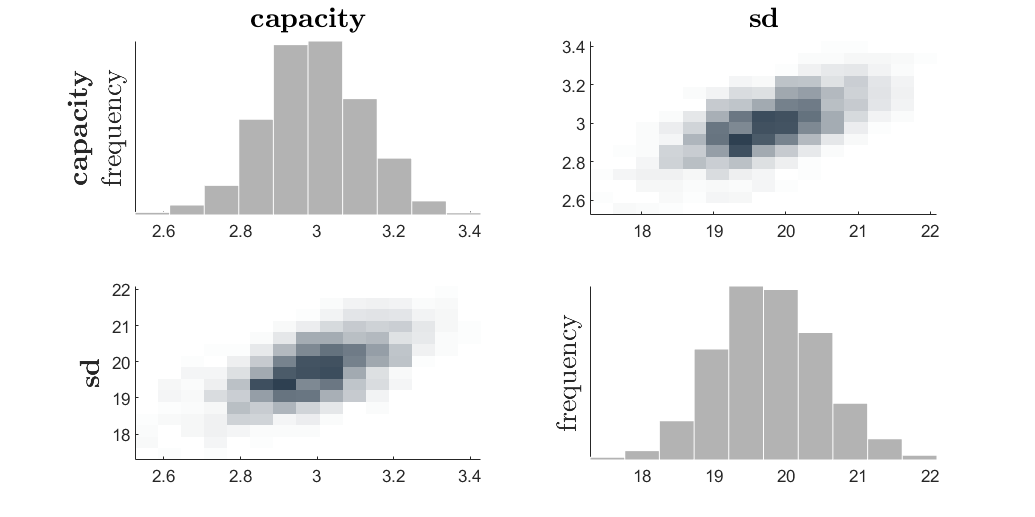

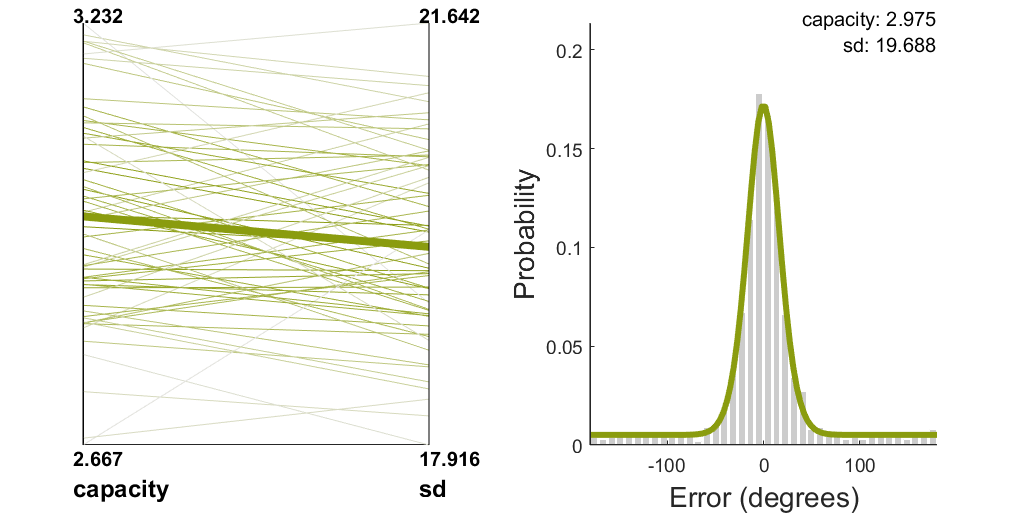

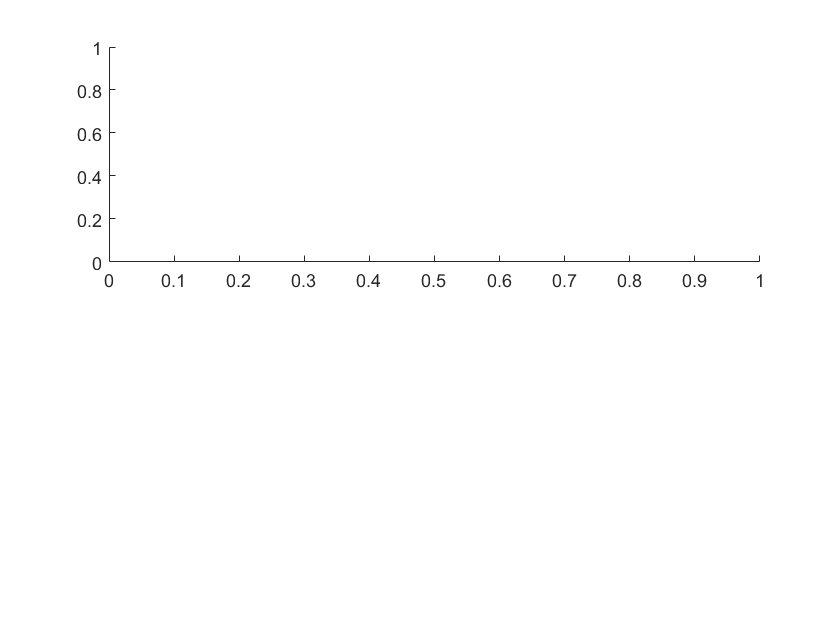

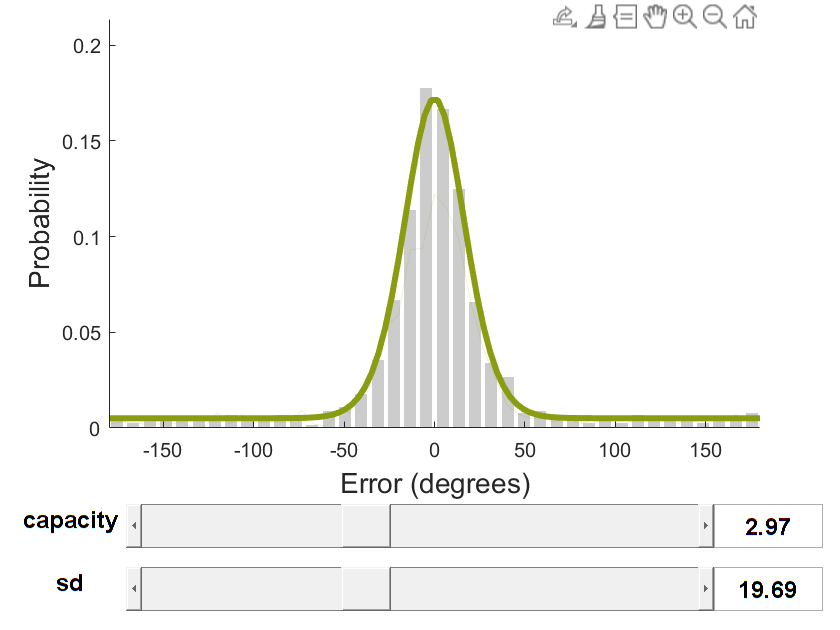

Error using awaitbar (line 91)
Input arguments of type matlab.ui.Figure not valid.

Error in PlotPosteriorPredictiveData (line 60)
      if awaitbar(i/length(which), curHandle)

Error in 

% data.n: 2 or 5
MemFit(data, SlotsPlusAveragingModel)